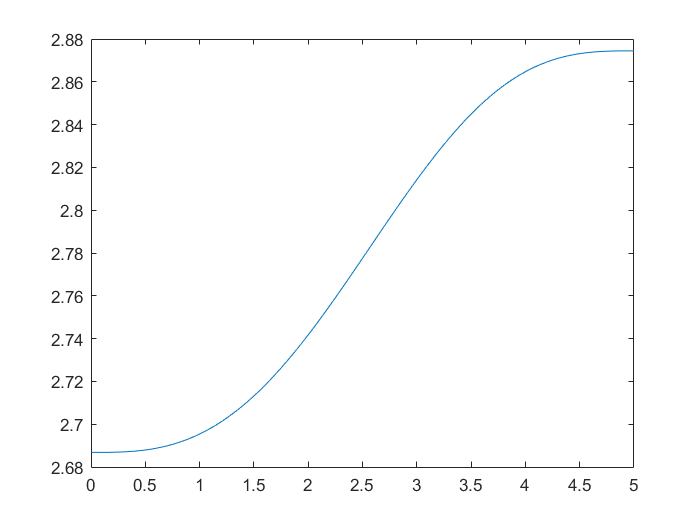

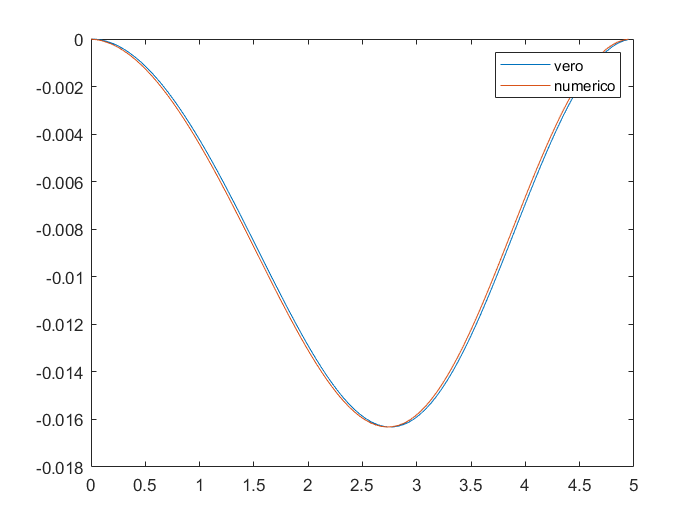

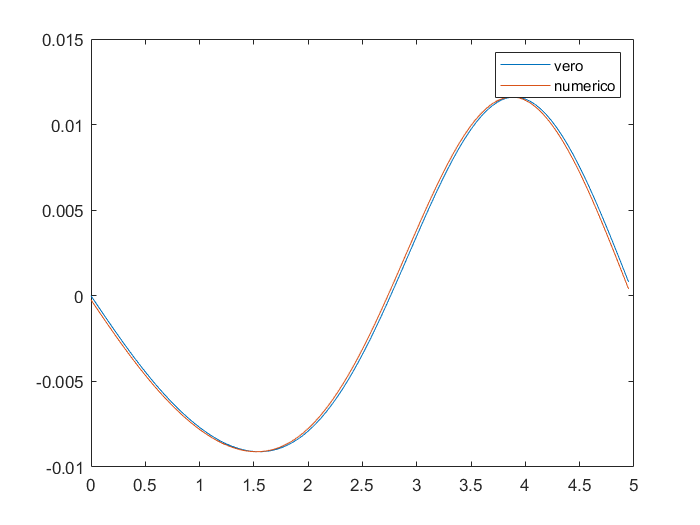

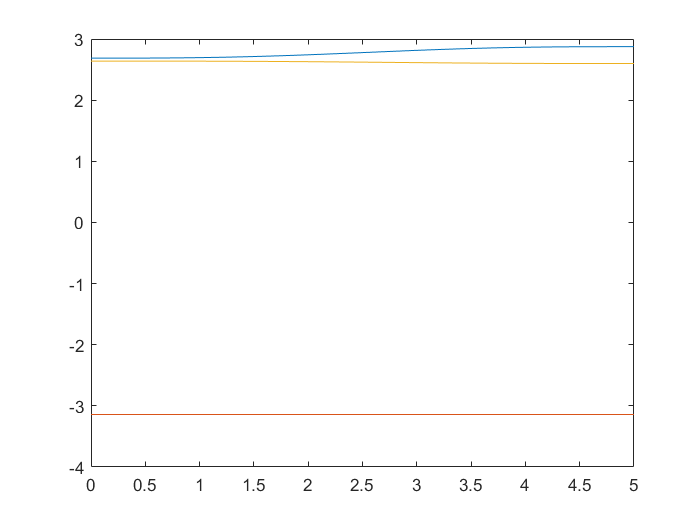

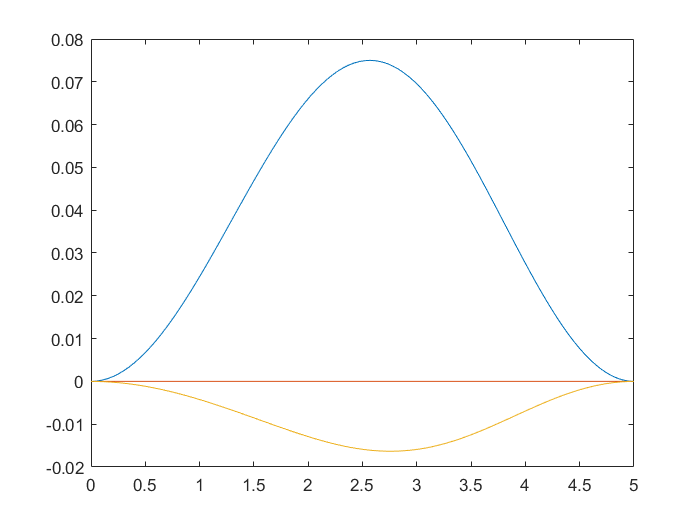

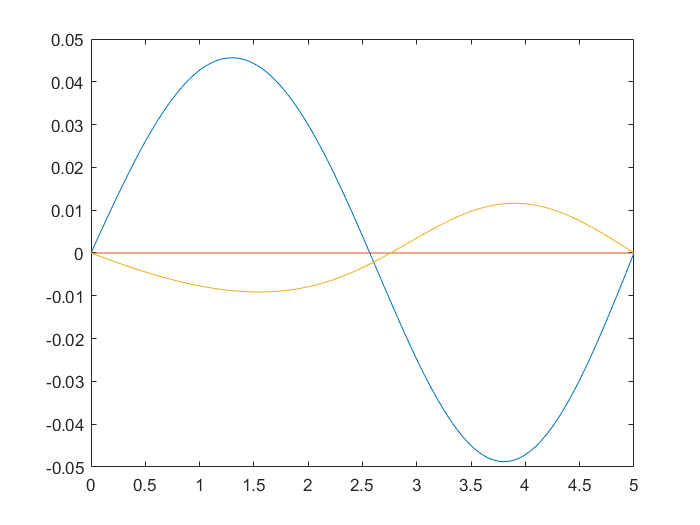

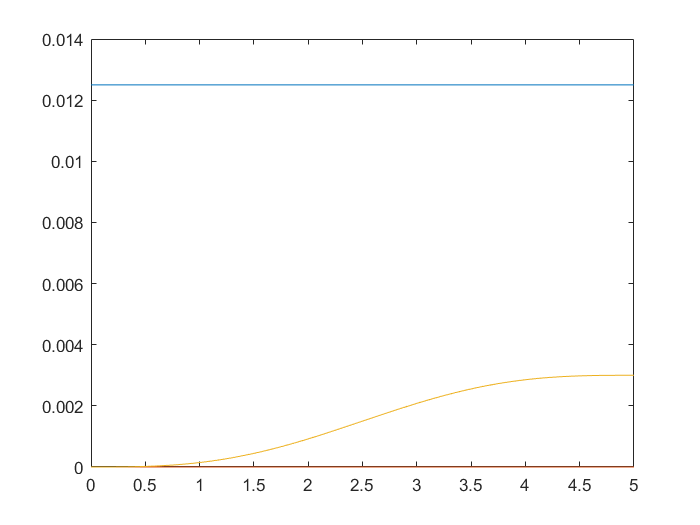

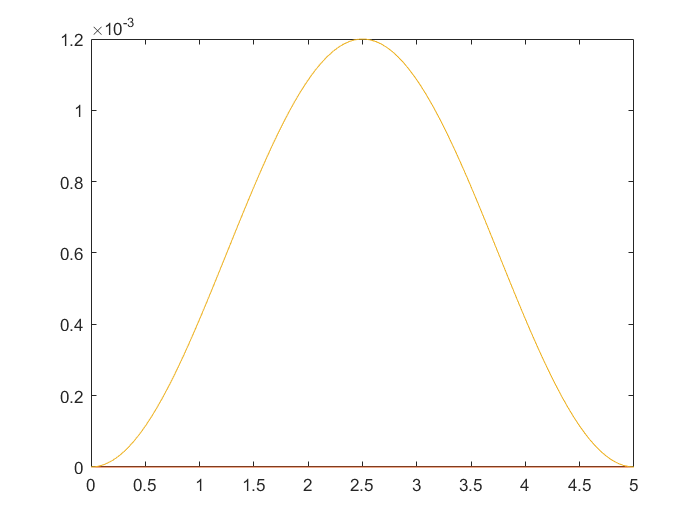

Cannot find an exact (case-sensitive) match for 'isWs'

The closest match is: isWS in D:\repository\Servo_System_progetto\Matlab\isWS.mlx


Error in TR4_move (line 5)
if  ~isWs(S)

clear all

load TR4_data.mat
S=[[5.7426e-3 4e-3 -2.4142e-3]',[9.0487e-3 5.5871e-3 2.7189e-3]'];

## movimento lineare

F=zeros(21,1);
[Ql,Qpl,Qppl,Fql,Tl,Xl,Xpl,Xppl] = TR4_linearMov(S,@Cicloidale,5,link,M,F);
plot(Tl,Ql(:,1))
qp=diff(Ql(:,3))/(Tl(2)-Tl(1));
qpp=diff(Qpl(:,3))/(Tl(2)-Tl(1));
plot(Tl(1:end-1),Qpl(1:end-1,3),Tl(1:end-1),qp)
legend("vero","numerico")
plot(Tl(1:end-1),Qppl(1:end-1,3),Tl(1:end-1),qpp)
legend("vero","numerico")
plot(Tl,Ql(:,1),Tl,Ql(:,2),Tl,Ql(:,3))
plot(Tl,Qpl(:,1),Tl,Qpl(:,2),Tl,Qpl(:,3))
plot(Tl,Qppl(:,1),Tl,Qppl(:,2),Tl,Qppl(:,3))
plot(Tl,Xl(:,1),Tl,Xl(:,2),Tl,Xl(:,3))
plot(Tl,Xpl(:,1),Tl,Xpl(:,2),Tl,Xpl(:,3))
plot(Tl,Xppl(:,1),Tl,Xppl(:,2),Tl,Xppl(:,3))
plot(Tl,Fql(:,1))
plot(Tl,Fql(:,2))
plot(Tl,Fql(:,3))

## movimento joint

F=zeros(21,1);
[Q,Qp,Qpp,Fq,T,X,Xp,Xpp] = TR4_jointMov(S,@Cicloidale,5,link,M,F);
xp=diff(X(1,:,3))/(T(2)-T(1));
plot(T(1:end-1),Xp(1,1:end-1,3),T(1:end-1),xp)
legend("vero","numerico")
xpp=diff(Xp(1,:,3))/(T(2)-T(1));
plot(T(1:end-1),Xpp(1,1:end-1,3),T(1:end-1),xpp)
legend("vero","numerico")
plot3(X(1,:,1),X(1,:,2),X(1,:,3))
title("traiettoria")
plot(T,Fq(1,:,1))
title('q1')
plot(T,Fq(1,:,2))
title('q2')
plot(T,Fq(1,:,3))
title('q3')
% save traiettoria_test X Ql T Q S

## movimento circolare

clear all
load TR4_data.mat
F=zeros(21,1);
S=[[5.7426e-3 4e-3 -2.4142e-3 1]',[9.0487e-3 5.5871e-3 2.7189e-3 1]',[8e-3 6e-3 3e-3 1]'];
[Qc,Qpc,Qppc,Fqc,Tc,Xc,Xpc,Xppc] = TR4_circularMov(S,@Cicloidale,5,link,M,F);
plot(Tc,Qc(1,:,3))
qp=diff(Qc(1,:,3))/(Tc(2)-Tc(1));
qpp=diff(Qpc(1,:,3))/(Tc(2)-Tc(1));
plot(Tc(1:end-1),Qpc(1,1:end-1,3),Tc(1:end-1),qp)
legend("vero","numerico")
plot(Tc(1:end-1),Qppc(1,1:end-1,3),Tc(1:end-1),qpp)
legend("vero","numerico")
plot(Tc,Qc(1,:,2))
qp=diff(Qc(1,:,2))/(Tc(2)-Tc(1));
qpp=diff(Qpc(1,:,2))/(Tc(2)-Tc(1));
plot(Tc(1:end-1),Qpc(1,1:end-1,2),Tc(1:end-1),qp)
legend("vero","numerico")
plot(Tc(1:end-1),Qppc(1,1:end-1,2),Tc(1:end-1),qpp)
legend("vero","numerico")
plot(Tc,Qc(1,:,1),Tc,Qc(1,:,2),Tc,Qc(1,:,3))
plot(Tc,Qpc(1,:,1),Tc,Qpc(1,:,2),Tc,Qpc(1,:,3))
plot(Tc,Qppc(1,:,1),Tc,Qppc(1,:,2),Tc,Qppc(1,:,3))
plot(Tc,Xc(1,:,1),Tc,Xc(1,:,2),Tc,Xc(1,:,3))
plot(Tc,Xpc(1,:,1),Tc,Xpc(1,:,2),Tc,Xpc(1,:,3))
plot(Tc,Xppc(1,:,1),Tc,Xppc(1,:,2),Tc,Xppc(1,:,3))
plot3(Xc(1,:,1),Xc(1,:,2),Xc(1,:,3))
plot(Tc,Fqc(1,:,1))
plot(Tc,Fqc(1,:,2))
plot(Tc,Fqc(1,:,3))

## movimento totale

clear all
close all
load TR4_data.mat
S=[[57.426e-3 4e-3 -2.4142e-3]',[9.0487e-3 44.871e-3 2.7189e-3]'];
F=zeros(21,1);
[Qm,Qpm,Qppm,Fqm,Tm,Xm,Xpm,Xppm]=TR4_move(S,7,@Cicloidale,link,M,F,'linear',Con);
xp=diff(Xm(1,:,2))/(Tm(2)-Tm(1));
plot(Tm(1:end-1),Xpm(1,1:end-1,2),Tm(1:end-1),xp)
legend("vero","numerico")
xpp=diff(Xpm(1,:,2))/(Tm(2)-Tm(1));
plot(Tm(1:end-1),Xppm(1,1:end-1,2),Tm(1:end-1),xpp)
legend("vero","numerico")
figure(1)
plot3(Xm(1,:,1),Xm(1,:,2),Xm(1,:,3))
hold on
TR4_plot(Qm(1,1,:),link,'b',1)
TR4_plot(Qm(1,end,:),link,'g',1)
title("traiettoria")
figure()
plot(Tm,Fqm(1,:,1))
title('q1')
plot(Tm,Fqm(1,:,2))
title('q2')
plot(Tm,Fqm(1,:,3))
title('q3')
